% Load variables
exp1_lab21 = load("C:\Users\amahesh\Olin\Projects\ENGR2410-01.26SP\lab_code\matlab\Lab2\exp1_lab21.mat");
I_in2 = exp1_lab21.I_in;
I_q = exp1_lab21.I_q;
V_in = exp1_lab21.V_in;
V_q2 = exp1_lab21.V_q;
clear exp1_lab21;

% Display results
I_in2,I_q,V_in,V_q2

I_in2 = 1.0e-03 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0005    0.0006    0.0007    0.0008    0.0009


I_q = 1.0e-04 *

   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0005    0.0005    0.0006    0.0007    0.0008    0.0009    0.0010    0.0012    0.0014    0.0015


V_in =     0.3000    0.3030    0.3060    0.3090    0.3120    0.3150    0.3180    0.3210    0.3240    0.3270    0.3300    0.3330    0.3360    0.3390    0.3420    0.3450    0.3480    0.3510    0.3540    0.3570    0.3600    0.3630    0.3660    0.3690    0.3720    0.3750    0.3780    0.3810    0.3840    0.3870    0.3900    0.3930    0.3960    0.3990    0.4020    0.4050    0.4080    0.4110    0.4140    0.4170    0.4200    0.4230    0.4260    0.4290    0.4320    0.4350    0.4380    0.4410    0.4440    0.4470


V_q2 =     0.3324    0.3346    0.3368    0.3393    0.3417    0.3443    0.3469    0.3498    0.3526    0.3556    0.3586    0.3617    0.3647    0.3678    0.3711    0.3743    0.3776    0.3808    0.3842    0.3876    0.3910    0.3944    0.3979    0.4013    0.4047    0.4082    0.4117    0.4152    0.4187    0.4222    0.4257    0.4293    0.4328    0.4363    0.4405    0.4439    0.4474    0.4508    0.4544    0.4579    0.4614    0.4649    0.4684    0.4720    0.4755    0.4790    0.4825    0.4861    0.4896    0.4932



semilogx(I_q, V_in, "o", "DisplayName","V source I measure")
hold on
semilogx(I_in2, V_q2, "o", "DisplayName","I source V measure")
xlabel("Current (A)")
ylabel("Voltage (V)")
title("Current Voltage Characteristic and Voltage Current Characteristic ")
currentQlog = log(I_q(5:101))

currentQlog =   -23.9198  -22.8517  -22.1741  -21.7734  -21.4748  -21.2120  -20.9765  -20.7719  -20.5357  -20.4897  -20.1913  -20.0680  -19.9078  -19.7639  -19.6152  -19.4712  -19.3378  -19.1950  -19.0459  -18.9397  -18.8290  -18.6777  -18.5527  -18.4316  -18.2983  -18.1811  -18.0569  -17.9261  -17.8162  -17.6907  -17.5692  -17.4457  -17.3310  -17.2110  -17.0908  -16.9770  -16.8584  -16.7397  -16.6240  -16.5056  -16.3851  -16.2710  -16.1503  -15.9213  -15.8094  -15.6895  -15.5780  -15.4603  -15.3466  -15.2272


currentINlog = log(I_in2(1:101))

currentINlog =   -20.7233  -20.5851  -20.4470  -20.3088  -20.1706  -20.0325  -19.8943  -19.7562  -19.6180  -19.4799  -19.3417  -19.2036  -19.0654  -18.9272  -18.7891  -18.6509  -18.5128  -18.3746  -18.2365  -18.0983  -17.9602  -17.8220  -17.6839  -17.5457  -17.4075  -17.2694  -17.1312  -16.9931  -16.8549  -16.7168  -16.5786  -16.4405  -16.3023  -16.1641  -16.0260  -15.8878  -15.7497  -15.6115  -15.4734  -15.3352  -15.1971  -15.0589  -14.9208  -14.7826  -14.6444  -14.5063  -14.3681  -14.2300  -14.0918  -13.9537



coeffs = polyfit(V_in(5:101), currentQlog,  1)

coeffs =    41.5621  -34.5071


coeffs2 = polyfit( V_q2, currentINlog, 1)

coeffs2 =    39.4555  -33.4597


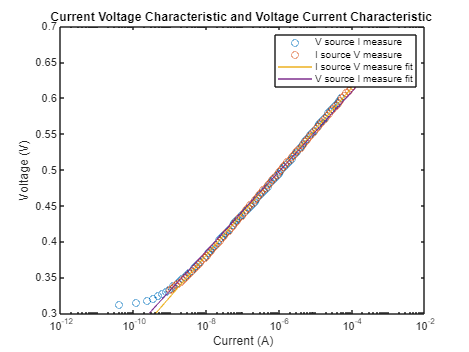

V_fit = linspace(min(V_in), max(V_q2), 1000);
I_qfit = exp(coeffs(1).*V_fit + coeffs(2));
I_infit = exp(coeffs2(1).*V_fit + coeffs2(2));
plot(I_infit, V_fit, "DisplayName","I source V measure fit")
plot(I_qfit, V_fit, "DisplayName","V source I measure fit")
% 
% semilogx(x, I_qfit, "DisplayName", "Fit V source I measure")
% semilogx(x, I_infit, "DisplayName", "Fit I source V measure")
legend()
hold off

I_vals = I_in2

I_vals = 1.0e-03 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0005    0.0006    0.0007    0.0008    0.0009


V_vals = V_q2

V_vals =     0.3324    0.3346    0.3368    0.3393    0.3417    0.3443    0.3469    0.3498    0.3526    0.3556    0.3586    0.3617    0.3647    0.3678    0.3711    0.3743    0.3776    0.3808    0.3842    0.3876    0.3910    0.3944    0.3979    0.4013    0.4047    0.4082    0.4117    0.4152    0.4187    0.4222    0.4257    0.4293    0.4328    0.4363    0.4405    0.4439    0.4474    0.4508    0.4544    0.4579    0.4614    0.4649    0.4684    0.4720    0.4755    0.4790    0.4825    0.4861    0.4896    0.4932



dV = V_vals(2:end) - V_vals(1:end-1);
dI = I_vals(2:end) - I_vals(1:end-1);
Inc_R = dV./dI

Inc_R = 1.0e+07 *

    1.4526    1.3324    1.2347    1.1060    0.9930    0.8958    0.8274    0.7305    0.6635    0.5809    0.5382    0.4361    0.3995    0.3684    0.3142    0.2775    0.2417    0.2204    0.1885    0.1642    0.1469    0.1279    0.1119    0.0962    0.0849    0.0748    0.0653    0.0560    0.0493    0.0427    0.0387    0.0327    0.0285    0.0297    0.0211    0.0184    0.0162    0.0145    0.0124    0.0108    0.0094    0.0082    0.0073    0.0063    0.0054    0.0047    0.0042    0.0036    0.0032    0.0027



loglog(I_vals(1: end - 1), Inc_R, "DisplayName","Expirimental Data")
inv_I = 1./I_vals(2:end);
A = inv_I'\Inc_R';
hold on
U_t = A

U_t = 0.0191

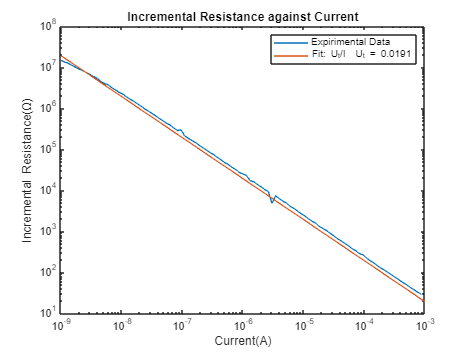

inc_R_fit = U_t./(I_vals);
loglog(I_vals, inc_R_fit, "DisplayName","Fit: U_t/I  U_t = 0.0191 mV")


xlabel("Current(A)")
ylabel("Incremental Resistance(\Omega)")
title("Incremental Resistance against Current")
legend()
hold off